% [y, Fs] = audioread('uLore.wav');
% info = audioinfo('uLore.wav');
% %sound(y, Fs);
% duracion = info.Duration;
% y = y(:,1);
% 
% % ventana = 100;
% % noverlap = 90;
% % NFFT = 128;
% % spectrogram(y, ventana, noverlap, NFFT, Fs, 'yaxis');
% % title('Espectrograma del audio - Lorena')
% % [s, w, t] = spectrogram(y, 'yaxis');
% 
% tiempo = 0;
% delta = 0.02;
% m = 0;
% 
% for tiempo = 0:delta:(duracion - delta)
%     inicio = floor(tiempo / (1 / Fs)) + 1;
%     fin = floor((tiempo + delta) / (1 / Fs)) + 1;
%     % W = rango de tiempo
%     w = y(inicio:fin); 
% 
%     try
%         [formante] =  obtenerFormantes(w, Fs, ' ');
%         m = m + 1;
%         tam = min(3, length(formante));
%         
%         Formantes(m, :) = [NaN, NaN, NaN];
%         
%        
%         Formantes(m, 1:tam) = formante(1:tam);
%         
%     catch ME
%         tiempo
%         sprintf('halp')
%     end   
% end
% plot(Formantes(:, 1), Formantes(:, 2), 'x')
% prom = nanmean(Formantes)


[y, Fs] = audioread('aLore.wav');
letraA = matrizFormantes(y, Fs, 'aLore.wav');

tiempo = 0

ans = 'halp'


% [y, Fs] = audioread('A_Mujer_22_1.wav');
% letraA2 = matrizFormantes(y, Fs, 'A_Mujer_22_1.wav');
% 
% [y, Fs] = audioread('A_Mujer_22_2.wav');
% letraA3 = matrizFormantes(y, Fs, 'A_Mujer_22_2.wav');

[y, Fs] = audioread('eLore.wav');
letraE = matrizFormantes(y, Fs, 'eLore.wav');

tiempo = 0

ans = 'halp'

tiempo = 0.0200

ans = 'halp'


[y, Fs] = audioread('iLore.wav');
letraI = matrizFormantes(y, Fs, 'iLore.wav');

tiempo = 0

ans = 'halp'

tiempo = 0.0200

ans = 'halp'


[y, Fs] = audioread('oLore.wav');
letraO = matrizFormantes(y, Fs, 'oLore.wav');

tiempo = 0

ans = 'halp'


[y, Fs] = audioread('uLore.wav');
letraU = matrizFormantes(y, Fs, 'uLore.wav');

tiempo = 0

ans = 'halp'

tiempo = 0.0200

ans = 'halp'

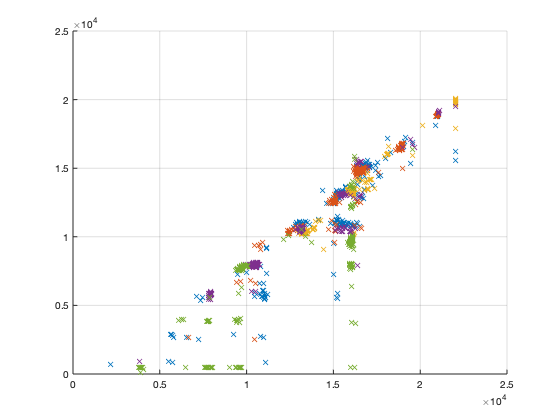


hold on
plot(letraA(:, 1), letraA(:, 2), 'x')
% plot(letraA2(:, 1), letraA2(:, 2), 'x')
% plot(letraA3(:, 1), letraA3(:, 2), 'x')

plot(letraE(:, 1), letraE(:, 2), 'x')

plot(letraI(:, 1), letraI(:, 2), 'x')

plot(letraO(:, 1), letraO(:, 2), 'x')

plot(letraU(:, 1), letraU(:, 2), 'x')

grid on
hold off

Prueba Hola Mundo

% [y, Fs] = audioread('oLore.wav');
% info = audioinfo('oLore.wav');
% duracion = info.Duration;
% y = y(:,1);
% 
% ventana = 100;
% noverlap = 90;
% NFFT = 128;
% spectrogram(y, ventana, noverlap, NFFT, Fs, 'yaxis');
% 
% load('BaseDeDatos.mat',"data");
% vocales = vertcat(data.formantes);
% 
% tiempo = 0;
% delta = 0.02; 
% 
% for tiempo = 0:delta:(duracion - delta)
%     inicio = floor(tiempo / (1 / Fs)) + 1;
%     fin = floor((tiempo + delta) / (1 / Fs)) + 1;
%     % W = rango de tiempo
%     w = y(inicio:fin); 
% 
%     try
%         [formanteAux] =  obtenerFormantes(w, Fs, ' ');
%         tam = min(3, length(formante));
%         formante = [NaN, NaN, NaN];
%         formante (1:tam) = formanteAux(1:tam);
%         %formante
%         
%         idx = knnsearch(vocales, formante);
%         objetivo = vocales(idx, :);
%         
%         for i = 1:length(data) 
%             if ismember(data(i).formantes, objetivo, 'rows') == [1, 1, 1]
%                 letra = data(i).val;   
%             end
%         end
%     catch ME
%         tiempo
%         sprintf('halp')
%     end   
% end

function [F] = obtenerFormantes (Audio, FS)

Canal1 = Audio(:,1);
n = length(Canal1);
ventana = hamming(n).*Canal1;

grado = 24;
filtro = filter([1 0.63], [1],ventana);
A = lpc(filtro, grado);

[h, w] = freqz([1],A,n);

h = 10*log10(abs(h));
w = (w * (FS/(2*pi)));

raices = roots(A).';
[R,indices,basura] = unique(real(raices));
I= imag(raices);
I = I(indices);

[theta,rho] = cart2pol(R,I);

Theta = (FS/(2*pi)) * theta;
Ancho_Banda = (-1/2)*(FS/(2*pi))*log(rho);
F = 0;

for i = 1:length(Ancho_Banda)
    if(Ancho_Banda(i)<400 & Theta(i)>90)
        if(F(1) == 0)
            F(1) = Theta(i);
        else
            F(end+1)=Theta(i);
        end
    end
end


end

function [FormantesLetra] = matrizFormantes (audio, Fs, nombre)
info = audioinfo(nombre);
    %sound(y, Fs);
    duracion = info.Duration;
    audio = audio(:,1);
    
    tiempo = 0;
    delta = 0.02;
    m = 0;
    
    for tiempo = 0:delta:(duracion - delta)
        inicio = floor(tiempo / (1 / Fs)) + 1;
        fin = floor((tiempo + delta) / (1 / Fs)) + 1;
        % W = rango de tiempo
        w = audio(inicio:fin); 
    
        try
            [formante] =  obtenerFormantes(w, Fs);
            m = m + 1;
            tam = min(3, length(formante));
            
            FormantesLetra(m, :) = [NaN, NaN, NaN];
            
           
            FormantesLetra(m, 1:tam) = formante(1:tam);
            
        catch ME
            tiempo
            sprintf('halp')
        end   
    end
end